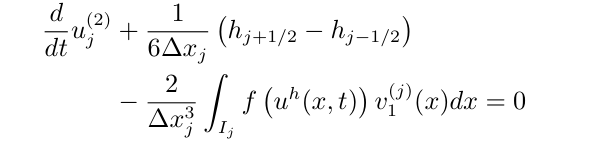

function s = Lh2(i)
global m_Hflux
global hstep
global Center
global Element


int2 = quadgk(@(x) fu(u(i,x)).*(x-Center(i)),Element(i,1),Element(i,2));
s =  (m_Hflux(i+1) - m_Hflux(i)) / (6 * hstep) - 2.0 * int2 / hstep^3;
s = -s;
end